sim = coppeliaRobot();

Creating robot
Connecting to Simulator
Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)
Connected to remote API server
Successfully connected to API server 


## Set up

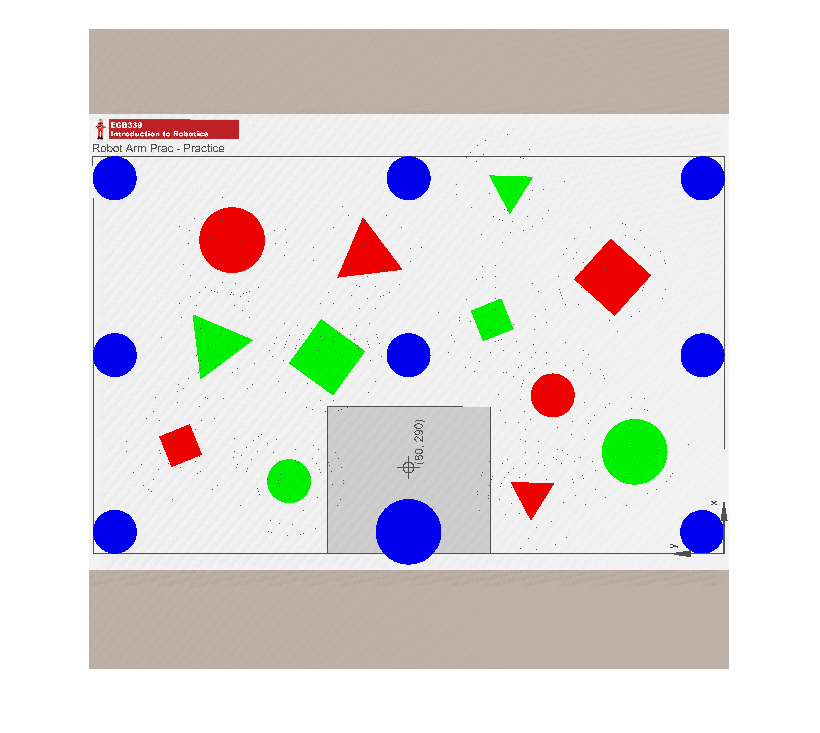

% q = getJointPositions(sim)
clear All; close all;

q = [0 -24 -21 45 0]; % Perfect for top view picture
q0 = [0 0 0 0 0];
setJointPositions(sim, q);
% % Capture image
image = getImage(sim);
imshow(image);

imwrite(image, 'capture.jpg');

% Set cylinders
init_xy = [300 500; 300 100; 100 100];
dest_xy = [300 400; 300 200; 150 150];

setCylinderPosition(sim, init_xy);

xy =     0.3000    0.5000
    0.3000    0.1000
    0.1000    0.1000


%% ----------------------------------------
%% Inverse Kinematics

% Robot specs
L1 = 138;
L2 = 135;
L3 = 147;
L4 = 60; L5 = 80; L6 = 100;   

% Robot position on workspace
xRobot = 80; yRobot = 290;

% Aim for cylinder 1 [300 500]
x = 300; y = 400; z = 50; % cylinder height/ in milimeter

phi = 0;    % angle of the vacuum gripper
phi0 = pi/2 - phi;

% y-yRobot
% x-xRobot
% y-yRobot/x-xRobot
theta1 = atan((y-yRobot)/(x-xRobot))

theta1 = 0.4636

rad2deg(theta1) 

ans = 26.5651


% distance_to_target_xy_plane
distance = sqrt((x-xRobot)^2 + (y-yRobot)^2) 

distance = 245.9675

omega = atan(L5/L4)

omega = 0.9273

ww = pi/2 - omega - phi; % fork-like icon
ww0 = omega + phi;

Lh = sin(ww)*L6

Lh = 60

Lv = cos(ww)*L6

Lv = 80

% pg30lec10
r = sqrt((distance - Lh)^2 + (z - L1+Lv)^2)

r = 186.1395

si = atan2((z - L1+Lv),(distance - Lh)) % s angle sign

si = -0.0430

L2

L2 = 135

L3

L3 = 147

r

r = 186.1395

beta = acos((L2^2 + L3^2 - r^2)/(2*L2*L3))

beta = 1.4398

beta * 180

ans = 259.1562

alpha = asin(sin(beta)/r*L3)

alpha = 0.8994


theta2 = pi/2 - alpha - si                                 %

theta2 = 0.7144

theta3 = pi/2 - beta   % Robot angle is already added 90 degrees, therefore minus it off

theta3 = 0.1310

theta4 = pi/2 - theta3 - theta2 + (pi/2 - phi0);            %
theta4 = - theta3 - theta2  % testing our way

theta4 = -0.8454


q_new = rad2deg([theta1 theta2 theta3 theta4 0])

q_new =    26.5651   40.9309    7.5080  -48.4389         0


setJointPositions(sim, rad2deg([theta1 theta2 theta3 theta4 0]));
% setJointPositions(sim, q_new);

% Suck
setSuctionCup(sim , 1)



## Back to origin

setJointPositions(sim, q0);

## Reach to destination

done = reach(dest_xy(2,1), dest_xy(2,2), sim)

q_new =   -22.2490   38.6173   11.9139  -50.5312         0


done = 1

## Drop

setSuctionCup(sim , 0)

## Origin

setJointPositions(sim, q0);

## Loop with given init_xy and dest_xy

setJointPositions(sim, q0);
for i = 1:3
    q_new = reach(init_xy(i,1), init_xy(i,2), sim);
    setSuctionCup(sim , 1);
    
    % origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 10);
    for q=q_mid'
        setJointPositions(sim, q);
        pause(0.01);
    end
    
    reach(dest_xy(i,1), dest_xy(i,2), sim);
    setSuctionCup(sim , 0);
    
    % origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 20);
    for q=q_mid'
        setJointPositions(sim, q);
        pause(0.01);
    end
end

## Process capture image

% replace image file with realtime image later
capture = double(imread("capture.jpg"));
% Zero the text part
plainImage = capture;
plainImage(1:122,:,:) = 0;
% plainImage = plainSpace(:,1:3015,:);  %double(plainspace(60:4619,129:2995,:));
% imshow(plainImage)

% Get colour plains
red = plainImage(:,:,1);
green = plainImage(:,:,2);
blue = plainImage(:,:,3);

% Clean noise, Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.6, ones(5,5));
% figure; imshow(blueCircles); title("blueCircles");

% Get blue shapes' stats
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles)
hold on
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
hold off


## Caluculate homgraphy

% Store data
blueCentroids = cat(1,blueStats.Centroid);
blueAreas = cat(1,blueStats.Area);

% Left bottom circle = start circle
startCircle = [min(blueCentroids(:,1)) min(blueCentroids(:,2)]
% largestArea = max(areas);
% i = find(areas == largestArea); % coordinates of the Largest circle


% Clone variable
centroidsNew = blueCentroids;
% Remove the largest circle
centroidsNew(i,:) = [];
% 3rd column: Calculate and add distanceFromLargest circle
distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-centroids(i,1)).^2 + abs(centroidsNew(:,2)-centroids(i,2)).^2)];
% 4th column: Add sum of coordinates
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)];
% Sort in the ascending order of distanceFromLargest
distanceSorted = sortrows( distanceFromLargest, 3);
sorted3 = sortrows( distanceSorted(1:3,:), 4);
sorted5 = sortrows( distanceSorted(4:8,:), 4);
% Now put them in P, order is right as required
P = [centroids(i,1:2)' sorted3(:,1:2)' sorted5(:,1:2)' ; ones(1,9) ];
% The Euclidean workspace coordinates of the markers
Q = [ 20 182.5 182.5 20 345 345 345 182.5 20; 560 560 290 290 560 290 20 20 20; ones(1,9) ];
H = simple_homography(P,Q);

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.